# **IO337 - Frame-Based Analog Loopback**

This example demonstrates using the analog I/O of the IO337 in frame-based sampling mode. Precise timing is achieved using the internal I/O module clock to update or sample the Analog-to-Digital Converters (ADC) or Digital-to-Analog Converters (ADC). CPU interrupts are used to synchronize the model execution on the CPU with the sampling of the analog signals. The sampling rate of the ADCs and DACs is an integer multiple of the CPU model rate. Frames of samples are transferred between the CPU and I/O module once per CPU model step in both directions. This setup makes it possible to achieve high analog sample rates while running the CPU at a lower model execution rate.

This example describes the required driver blocks and settings. The model generates four sine wave signals on the analog outputs. In contrast to the single-sample operation mode, the frame-based approach allows you to generate or acquire signal frequencies above the CPU model execution rate. The analog output pins of the module must be wired to the analog inputs to feedback the signals into the model for logging and visualization.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO337 I/O module installed

- A Speedgoat configuration file for the IO337 module (every configuration file for these modules supports the analog interfaces)

- Connector cable from the I/O module to the terminal board

- 1x 100-pin terminal board with jumper wires

- Optional: Oscilloscope to measure the analog signals

### Test Setup

Connect the IO337 module with the cable to the 100-pin terminal board. Note the indications on the connectors of the cable to ensure the right connector is connected to the I/O module and terminal board respectively (the cable is not symmetrical). The arrows on the connectors help to ensure that the orientation is right. Locate the DAC channels 1 to 4 and connect them to the positive pin of the differential analog input channels 1 to 4 according to the table below. The analog output signals are single ended. Therefore, connect the negative pins of each differential analog input channel to ground.

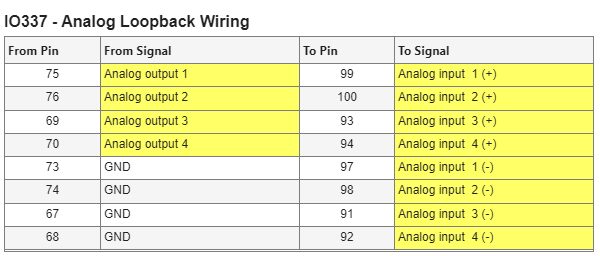

The complete pin mapping is available in [IO337 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io337_650k_pin_mapping).

## Initialize and Open the Simulink model

Open the Simulink model manually or use the following commands.

 
% Open Simulink model
modelName = 'sgMdl_IO337_AnalogLoopbackDMA';
open_system(modelName);

Before the Simulink model can be built, the I/O module and configuration file must be specified in the IO3xx Setup block, as this example can be executed on different configurable I/O modules. First, open the mask of the IO3xx Setup block and select your I/O module from the drop-down. Once the mask has extended, select a configuration file. This example only requires analog interfaces, which are supported by any configuration file for the IO337 by default.

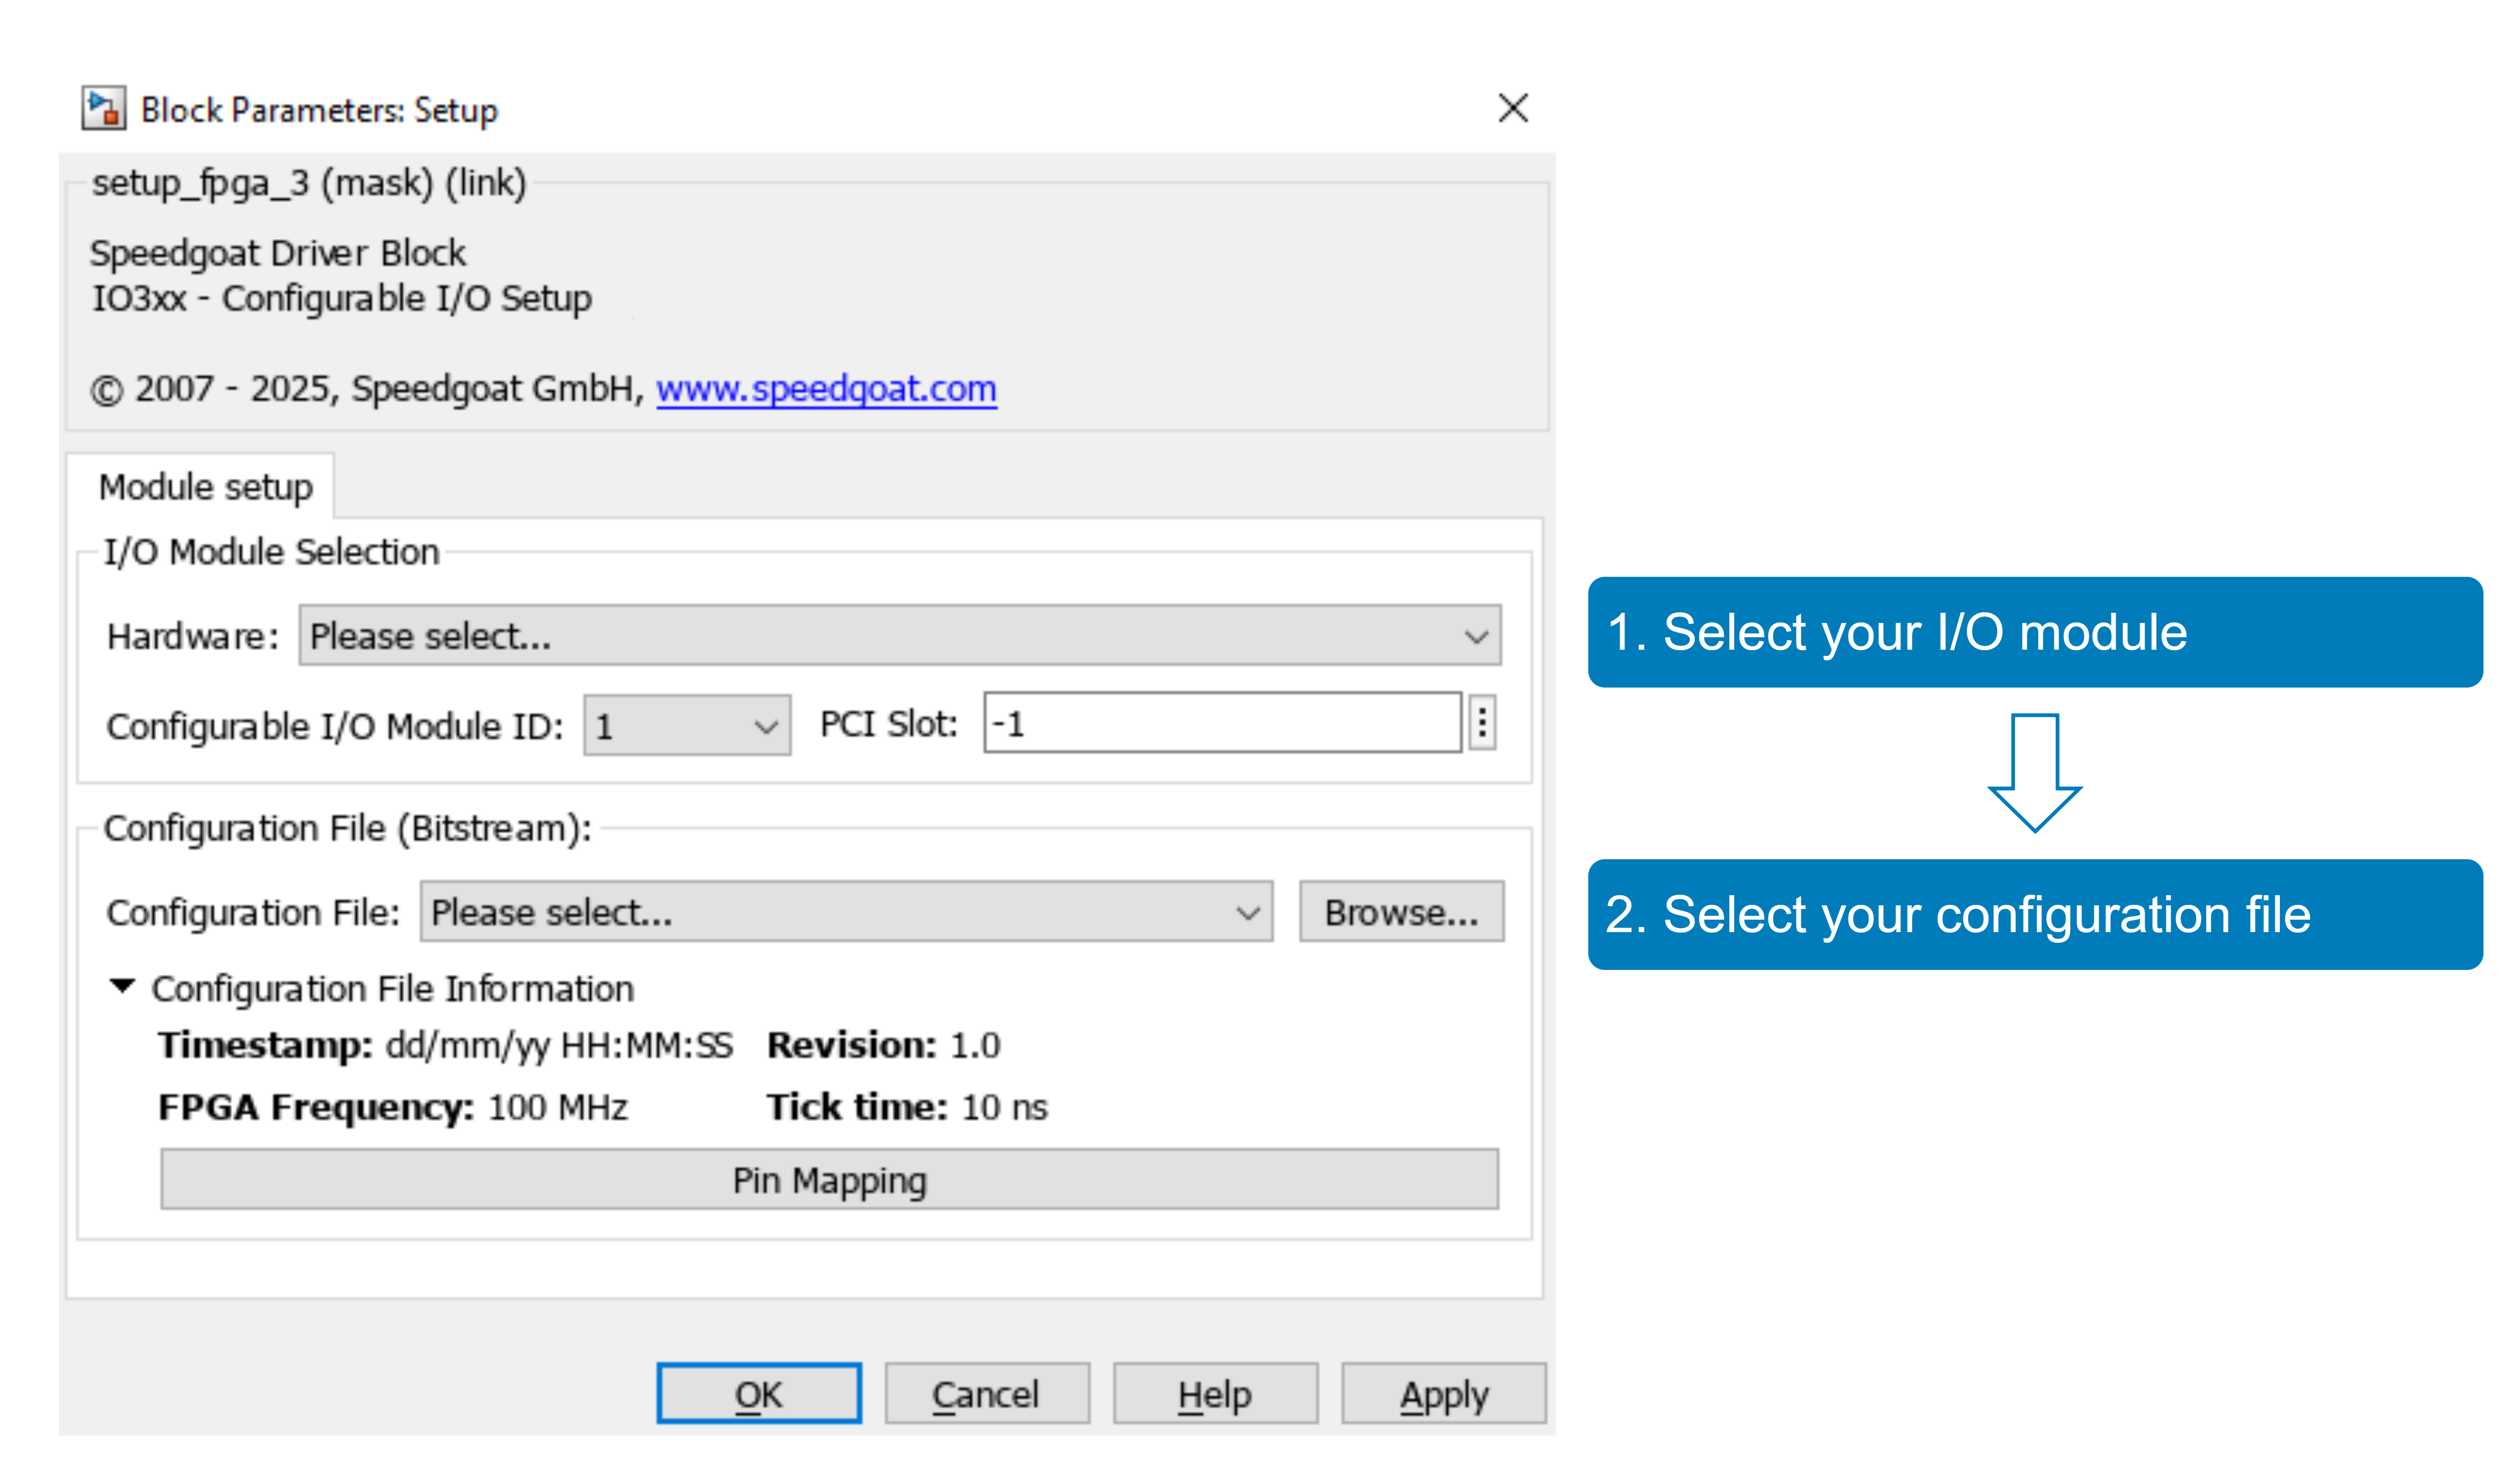

Click the **Pin Mapping** button to check where the functionalities are located.

## Model Description

### General Setup

The Simulink model features the [IO3xx Setup v3](https://www.speedgoat.com/help/slrt/page/io_main/refentry_fpga_setup_io337_650k), [IO337 Analog Setup v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io337_analog_setup_v1), [IO337 Analog Input v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io337_analog_input_v1), and [IO337 Analog Output v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io337_analog_output_v1) blocks. The analog driver blocks used in this model support the IO337 module. 

Settings are shared between the [IO3xx Setup v3](https://www.speedgoat.com/help/slrt/page/io_main/refentry_fpga_setup_io337_650k), [IO337 Analog Setup v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io337_analog_setup_v1), [IO337 Analog Input v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io337_analog_input_v1), and [IO337 Analog Output v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io337_analog_output_v1) blocks. Ensure that you select the same FPGA Module Identifier in the mask of these blocks. This is important for Simulink to identify which blocks belong together and which I/O module they address. This is especially important if you have multiple configurable I/O modules in your system.

The analog outputs of the IO337 are single ended. Note that the analog input circuits expect differential signals. The example model uses four analog output channels to generate four sine wave signals. Four analog input channels are used to read back the signals for logging and visualization.

### Frame-Based Operation Mode

The analog inputs and outputs are configured in the [IO337 Analog Setup v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io337_analog_setup_v1) block. In this example, the ADCs and the DACs run in frame-based mode. They are sampled based on the module internal clock according to the sample rate defined in the  [IO337 Analog Setup v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io337_analog_setup_v1) block. A frame of samples is transferred in both directions between the CPU and I/O module once every CPU model execution step. The CPU block sample time must be an integer multiple of the ADC and DAC sample rate. The **Frame Size** is the ratio between the two rates.

On the analog input side, the I/O module emits an interrupt as soon as a frame of samples has been acquired, and the data has been transferred to the CPU memory. The CPU wakes up when the interrupt is received and processes the data which is available in the system memory. This setup avoids unnecessary waiting times for the CPU. High sample rates can be achieved while running the CPU at a lower rate.

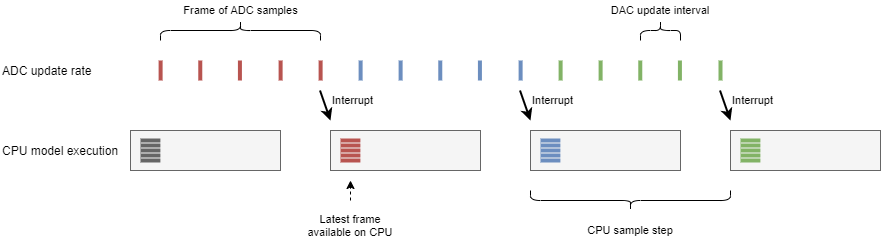

On the analog output side, the behavior is slightly different. The CPU writes a frame of data to a buffer on the I/O module. The module reads out one sample at a time from the buffer and updates the DAC. This process happens at the sample rate defined in the analog setup block*, *and is triggered based on the module internal clock. 

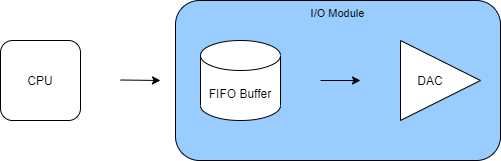

Once the number of samples in the buffer falls below a defined threshold, an interrupt is emitted to signal to the CPU that the buffer must be filled with new data. The CPU ([IO337 Analog Output v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io337_analog_output_v1) block) must write the next frame to the buffer before it is empty. This setup is required to ensure that the buffer is never empty, and that the module always has data available to update the outputs at the defined rate.

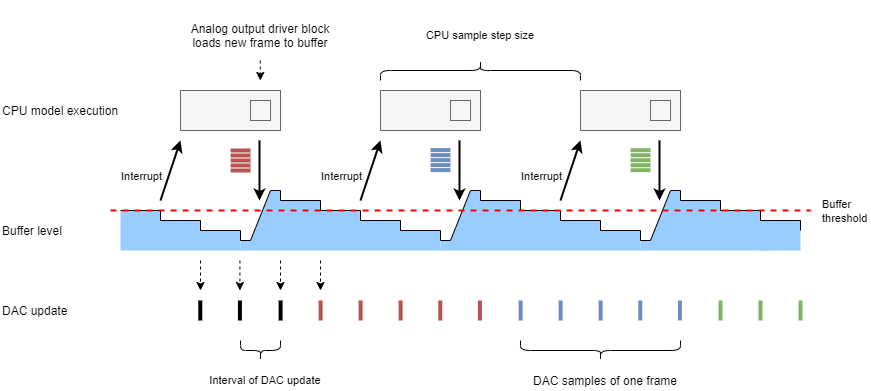

## Sample Rate and Frame Settings

The model is configured to run at a fixed-step sample rate of 1 ms. The frequency of the generated sine waves is 2 kHz. The frame size is set to 100. 

 
% ----------------------------------
% Model parameters
% ----------------------------------

Ts = 1e-3;                  % CPU model sample step size [s]
SineFrequency = 2e3;        % Frequency of generated sine wave signals [Hz]
FrameSize = 100;            % Frame size

% ----------------------------------
% Verification
% ----------------------------------

AnalogSampleRate = FrameSize/Ts     % Sample rate of the ADCs and DACs
SamplesPerPeriod = AnalogSampleRate/SineFrequency   % Number of samples per signal period

The settings result in a sample rate of 100 KSPS for the ADCs and DACs, meaning the DACs and ADCs are updated 50 times per sine wave period.

### ADC and DAC Settings

To see the setup and parametrization of the ADC and DAC channels, open the [IO337 Analog Setup v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io337_analog_setup_v1) block.

#### Tab: Main

In the main tab of the [IO337 Analog Setup v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io337_analog_setup_v1) block, the **ADC Sample Trigger** and **DAC Sample Trigger** parameters are both set to **I/O Module Clock**. 

The **Enable DMA Interrupt** checkboxes are selected for the analog inputs and outputs. Therefore, the **Frame-Based Settings** parameter groups of the block mask are visible. The **Sample Rate [Hz]**, **Frame Size**, and **Block Sample Time [s]** can be defined for the analog inputs and outputs. These three parameters have a fixed relation to each other. The **Frame Size** is the ratio between the **Sample Rate** and the **Block Sample Time**. Out of the three parameters, only two can be explicitly defined. The third parameter is automatically derived by the driver block. Its edit field must be set to "-1". The user can choose which two parameters are explicitly defined.

The sample rate achievable is restricted by the clock rate of the FPGA. The resolution is indicated in the **Trigger Module Resolution [s] **field. One sample interval must be a multiple of one FPGA tick (clock period). The adjusted sample rate values are indicated in the block mask to the right of the edit fields. 

Additionally, in the analog output **Frame-Based Settings** parameter group, the **FIFO Threshold** can be defined. It is set to 20 % of the **Frame Size** to give the CPU enough time to re-fill the buffer before it is empty.

#### Tab: Analog Inputs

In the **Analog Inputs** tab of the [IO337 Analog Setup v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io337_analog_setup_v1) block, you can see which ADC channels are active, and the configured voltage range. In this example, ADC channels 1 to 4 are active. Note that all analog inputs of the IO337 expect differential signals. The voltage range is +/-10 V (or +/- 2.5 V, depending on the hardware variant), which refers to the differential signal range. 

#### Tab: Analog Outputs

In the **Analog Outputs** tab of the [IO337 Analog Setup v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io337_analog_setup_v1) block, you can see which DAC channels are active and the configured voltage range. The voltage range is set to +/- 10 Volts for the single-ended output signals.

### Analog Input (ADC) and Analog Output (DAC) Blocks

The analog channels are configured in the [IO337 Analog Setup v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io337_analog_setup_v1) block. The [IO337 Analog Setup v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io337_analog_setup_v1) and [IO337 Analog Output v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io337_analog_output_v1) blocks serve as interfaces to connect the input and output signals in the Simulink model. The input and output ports of the [IO337 Analog Setup v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io337_analog_setup_v1) and [IO337 Analog Output v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io337_analog_output_v1) blocks are updated as soon as you apply the channel settings in the setup block. The number of ports corresponds to the number of activated channels.

The [IO337 Analog Output v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io337_analog_output_v1) block is located within the Analog Sine Wave Generator function call subsystem. The frame-based sine wave signals are generated with a trigonometric function block and a wrapped integrator in the **Compute Phase (Frame-Based)** subsystem. The subsystem outputs a frame of phase values between 0 and 2*pi.

Note, the signal dimension of the ports of the [IO337 Analog Output v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io337_analog_output_v1) block and [IO337 Analog Setup v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io337_analog_setup_v1)[ ](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io336_analog_input_v1)block is 100. It must be equal to the frame size.

## **Interrupts and Synchronization**

Two instances of the [Interrupt Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_interrupt_setup) block are used to handle the interrupts emitted by the analog in- and output interfaces. As described above, the analog output interface emits an interrupt to signal to the CPU that the data buffer needs to be re-filled. The analog input interface signals through an interrupt that a new frame is available in the system memory.

The Interrupt Setup 1 block must be configured to act on the **Speedgoat IO337-650k Analog output interrupt**. It activates the Analog Sine Wave Generator function call subsystem when an interrupt is received. The content of the subsystem including the [IO337 Analog Output v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io337_analog_output_v1) driver block is executed as an asynchronous task.

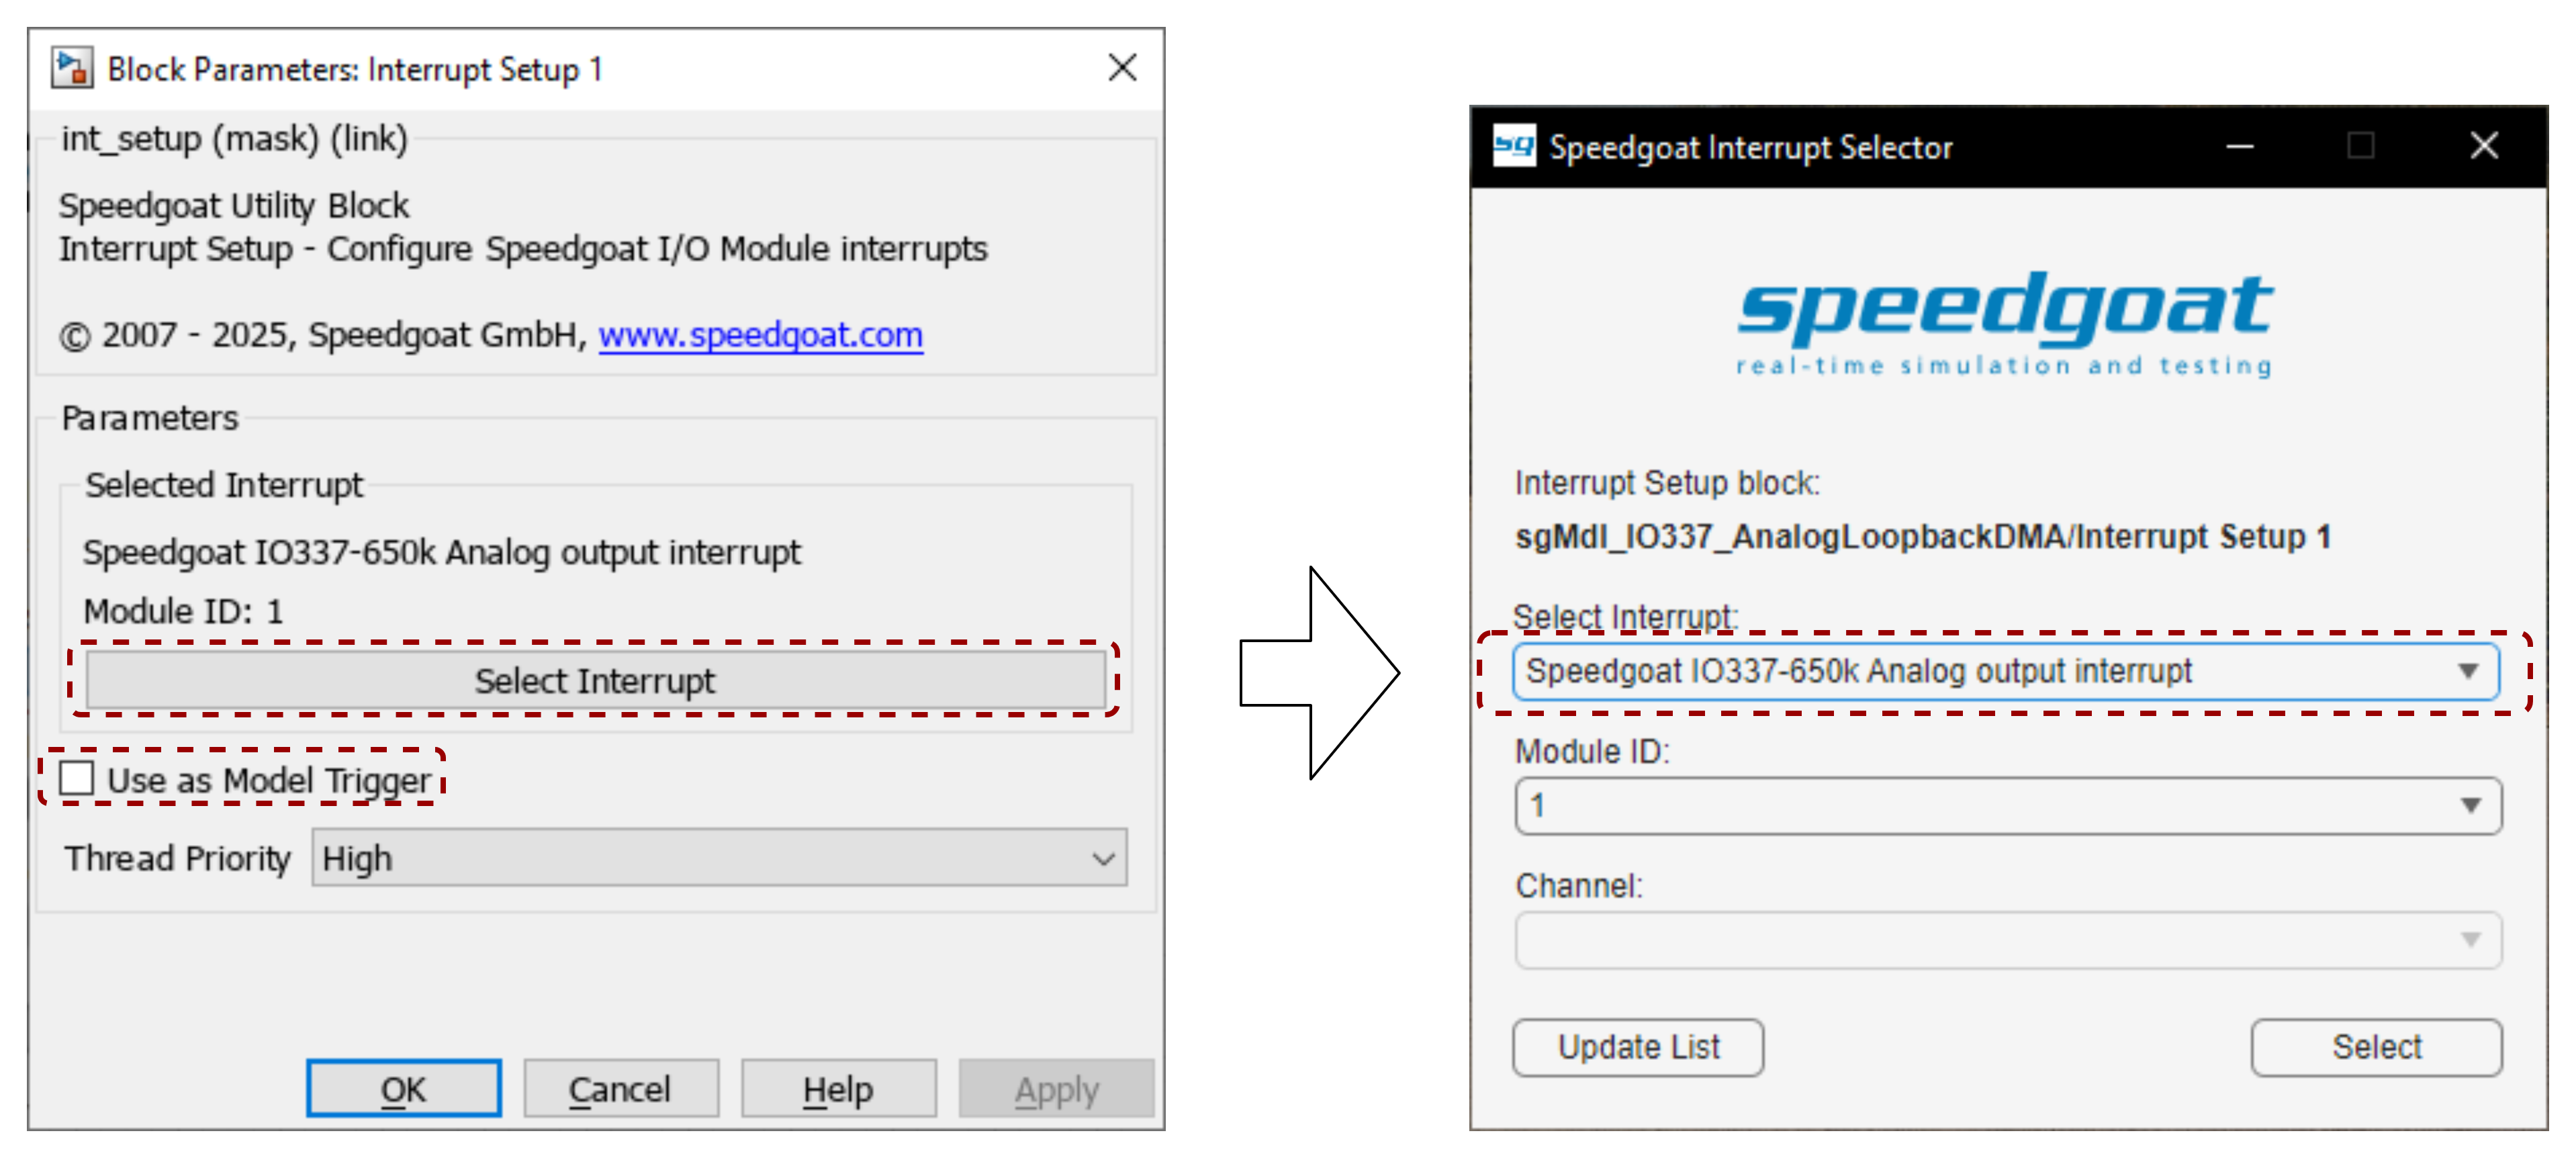

The Interrupt Setup 2 block must be configured to act on the **Speedgoat IO337-650k Analog input interrupt**. The **Use as model trigger** checkbox is active. This means that the entire model execution on the CPU is triggered every time an interrupt from the analog input interface is received (except for the asynchronous task with the [IO337 Analog Output v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io337_analog_output_v1) block in the function call subsystem). It is important that the analog output sample time setting in the [IO337 Analog Setup v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io337_analog_setup_v1) block matches the sample time of the model.

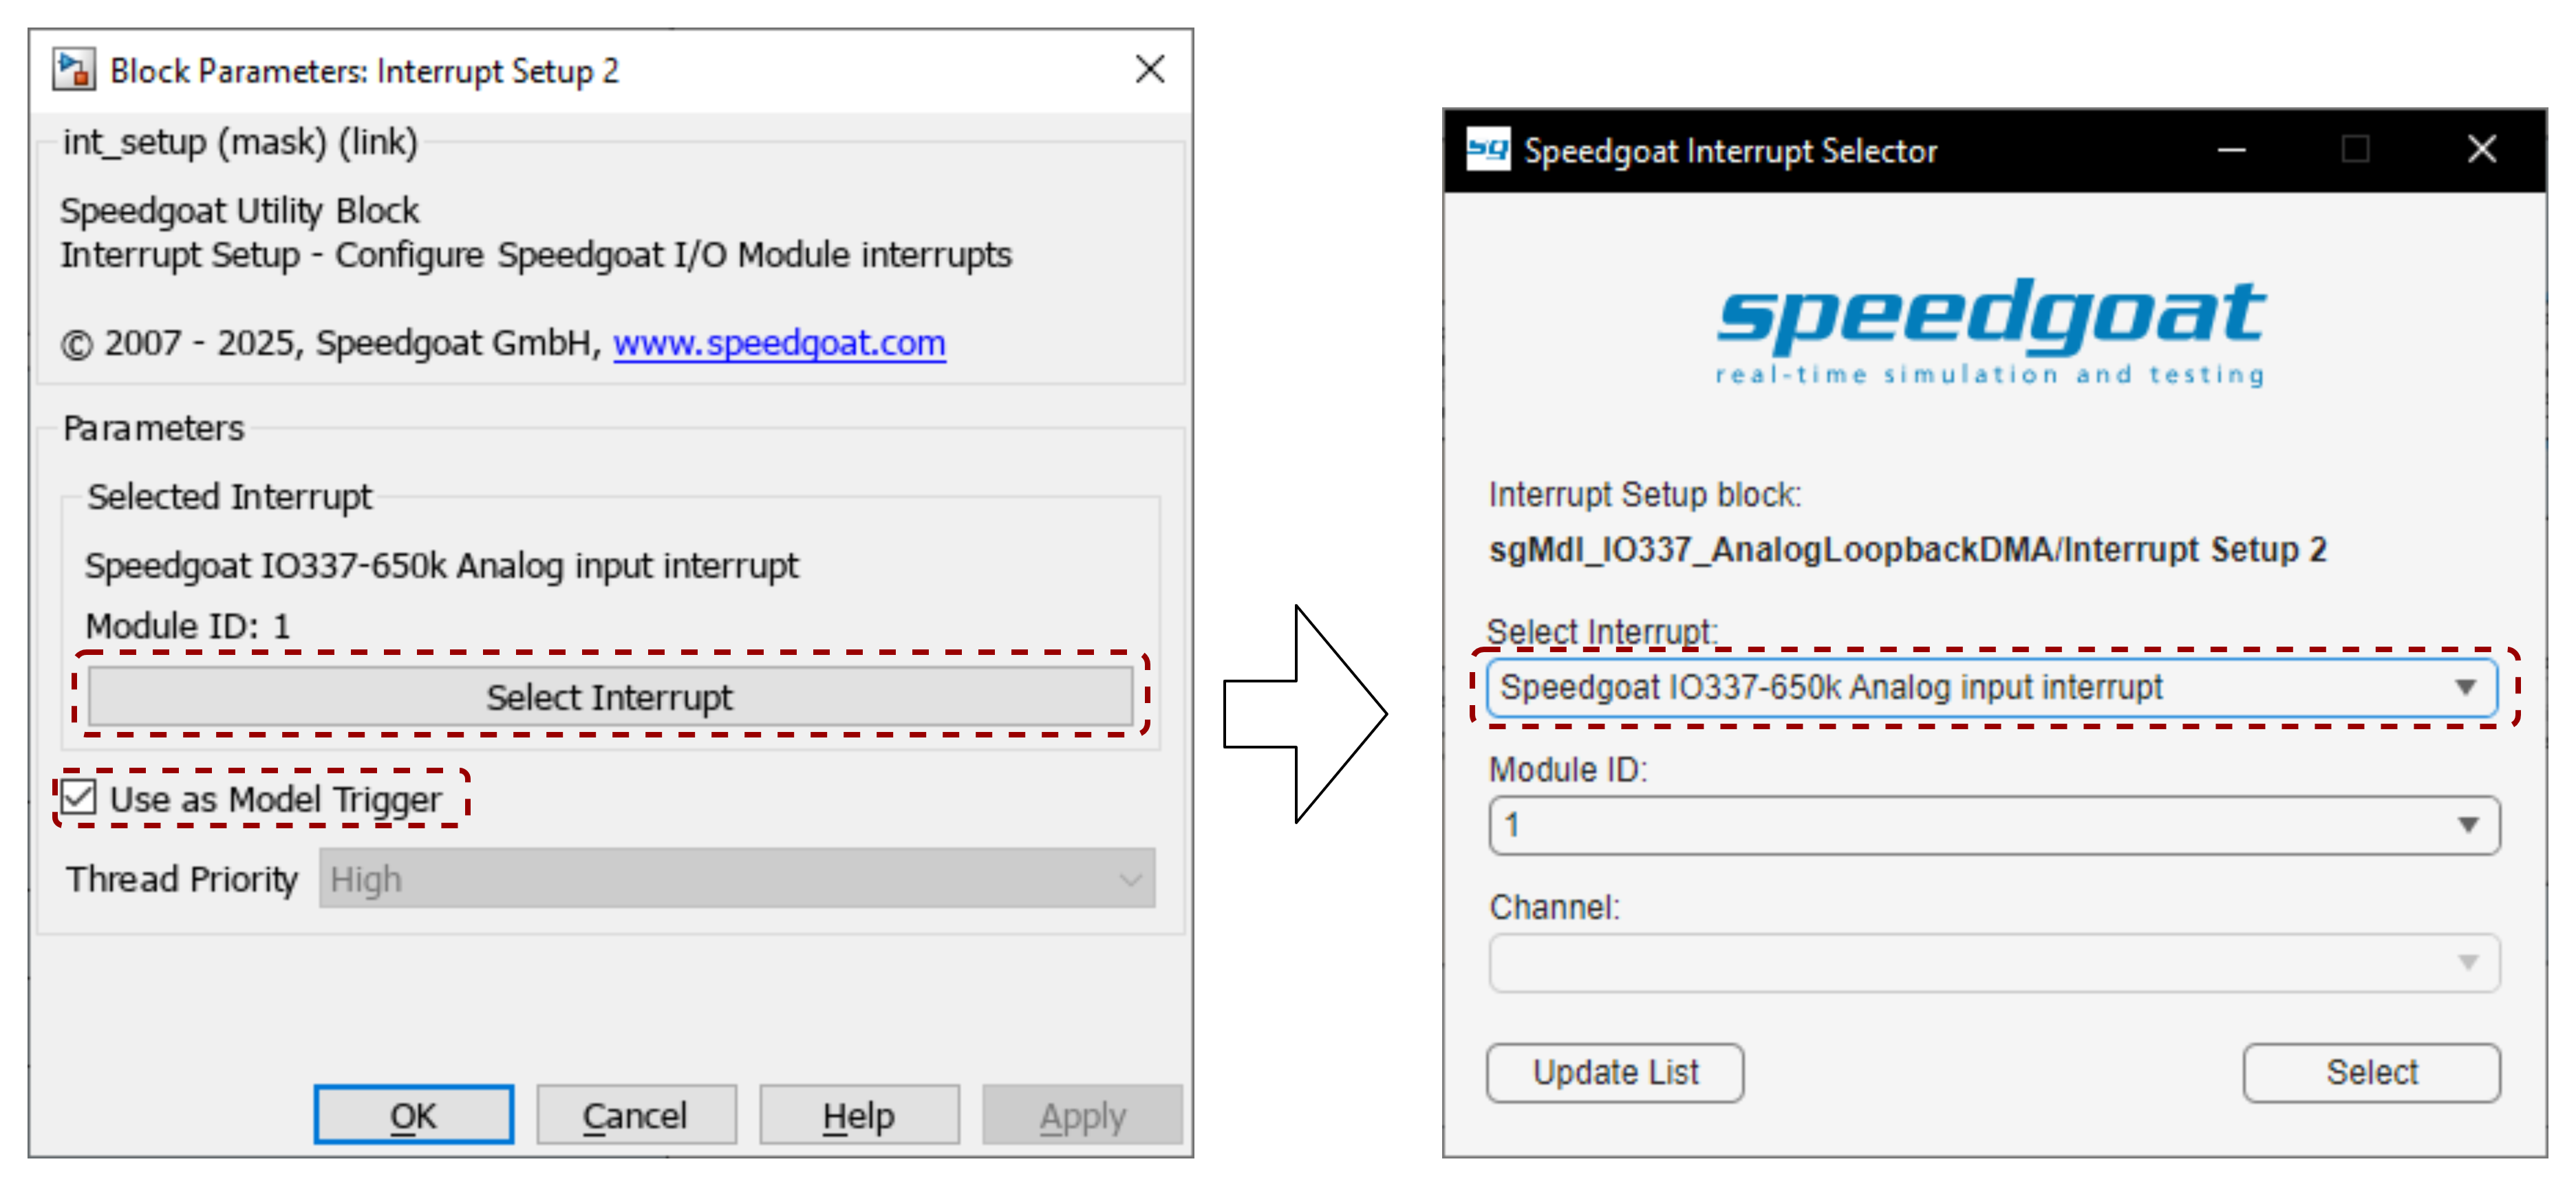

## Logging

The sine wave signals are frame-based. They are handled as vectors in the Simulink model. File log blocks are used to log the signals on the target machine. The **Input Processing** must be set to **Columns as channels (frame-based)** in the block mask of the **File Log** blocks for correct visualization.

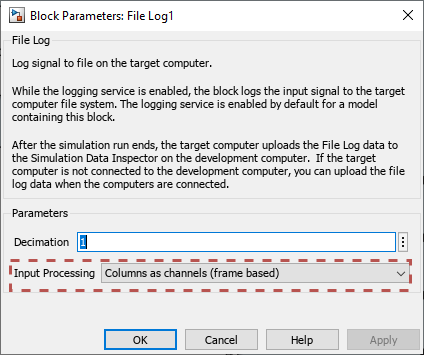

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Set the stop time to 1 seconds
set_param(modelName,'StopTime','1');

% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Start the real-time application
tg.start;

## Show and Analyze the Signals

To show the measured signals, either run the following code section or click the **Data Inspector** button in the **REAL-TIME** tab in the Simulink model. The File Log block is used to log the signals. The signals become visible in the Data Inspector after the model execution has stopped.

 
% Get and configure SDI Run
SDIRun      = Simulink.sdi.Run.getLatest;   % get the latest SDI run
SDIRun.name = 'Real-Time Simulation';

% clear and configure plot layout
Simulink.sdi.clearAllSubPlots
Simulink.sdi.setSubPlotLayout(1,1);         % layout with one plots

% get signals by name (signal label in Simulink)
ADC_Signal1 = SDIRun.getSignalsByName('ADC 1');
ADC_Signal2 = SDIRun.getSignalsByName('ADC 2');
ADC_Signal3 = SDIRun.getSignalsByName('ADC 3');
ADC_Signal4 = SDIRun.getSignalsByName('ADC 4');

% assign ADC signals to subplot 1
plotOnSubPlot(ADC_Signal1,1,1,true);
plotOnSubPlot(ADC_Signal2,1,1,true);
plotOnSubPlot(ADC_Signal3,1,1,true);
plotOnSubPlot(ADC_Signal4,1,1,true);

% open SDI
Simulink.sdi.view;
Simulink.sdi.setSubplotLimits(1,1,"tMin",0.995,"tMax",1);   % set time span
Simulink.sdi.setSubplotLimits(1,1,"yMin",-5,"yMax",5);      % set y-zoom

The four sine wave signals with an amplitude from 1 to 4 V are displayed in the Simulation Data Inspector (SDI). Note that the frequency is higher than the model execution rate which is possible due to the frame-based approach.

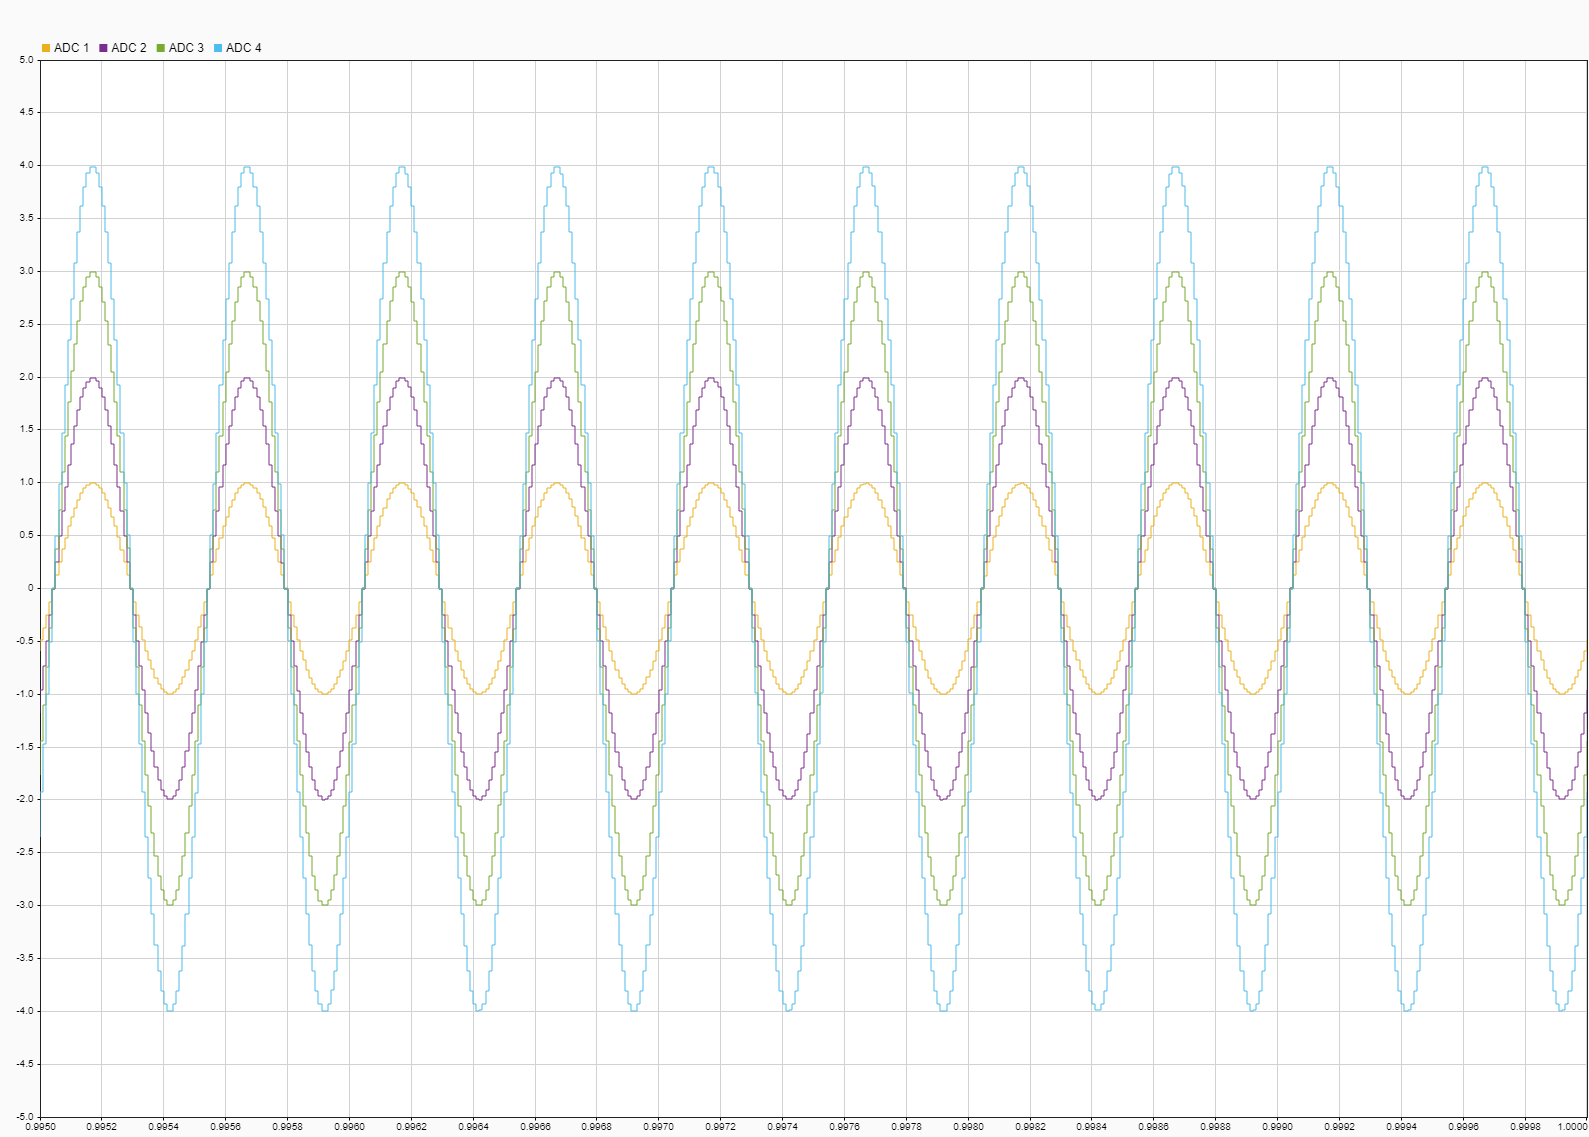

## Additional References

- [IO337 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io337_650k)

- [Analog IO337](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_analog_io337_650k)